%load data
confidence = load('..\analyzed\DM101_unsmoothed\group_accuracy.mat');
%this is from colorbrewer: http://colorbrewer2.org/#type=sequential&scheme=BuGn&n=3
load('cb.mat');

Error using load
Unable to read file 'cb.mat'. No such file or directory.


detection_confidence = load('..\analyzed\DM102_unsmoothed\group_accuracy_detection.mat');
detection_confidence = detection_confidence.group_accuracy_detection;
ss = find(~isnan(detection_confidence(1,:)));
detection_confidence = detection_confidence(:,ss);

discrimination_confidence = load('..\analyzed\DM102_unsmoothed\group_accuracy_discrimination.mat');
discrimination_confidence = discrimination_confidence.group_accuracy_discrimination(:,ss);

detection_to_discrimination = load('..\analyzed\DM102_unsmoothed\group_accuracy_cross1.mat');
detection_to_discrimination = detection_to_discrimination.group_accuracy_cross1(:,ss);

discrimination_to_detection = load('..\analyzed\DM102_unsmoothed\group_accuracy_cross2.mat');
discrimination_to_detection = discrimination_to_detection.group_accuracy_cross2(:,ss);

YN_to_discrimination = load('..\analyzed\DM103_unsmoothed\group_accuracy_cross1.mat');
YN_to_discrimination = YN_to_discrimination.group_accuracy_cross1(:,ss);

discrimination_to_YN = load('..\analyzed\DM103_unsmoothed\group_accuracy_cross2.mat');
discrimination_to_YN=discrimination_to_YN.group_accuracy_cross2(:,ss);

YN = load('..\analyzed\DM103_unsmoothed\group_accuracy_YN.mat');
YN = YN.group_accuracy_YN(:,ss);

dis_cross_det = mean(cat(3,discrimination_to_detection,detection_to_discrimination),3);
dis_cross_YN = mean(cat(3,discrimination_to_YN,YN_to_discrimination),3);
dis_mean_det = mean(cat(3,discrimination_confidence,detection_confidence),3);
ROI_names = {'union FPl','union FPm','union 46','ventralStriatum',...
    'vmPFC roi','precun roi','pMFC roi','ventricles roi'};


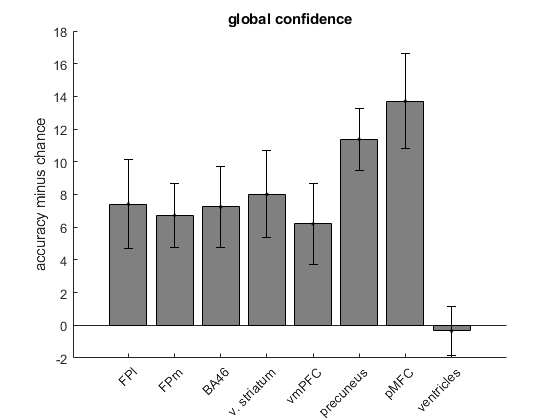

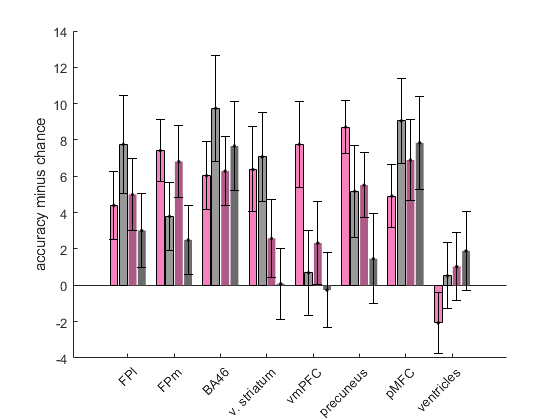

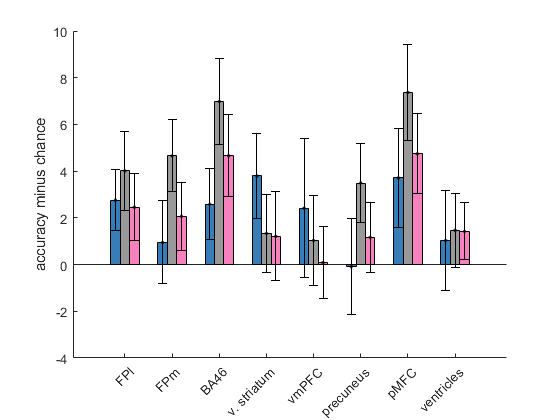

cl =     0.5529    0.8275    0.7804
    0.9843    0.5020    0.4471


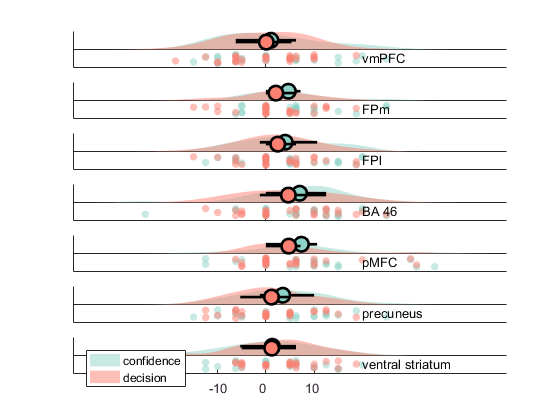

cl =     0.5529    0.8275    0.7804
    0.7020    0.8706    0.4118
    0.9922    0.7059    0.3843


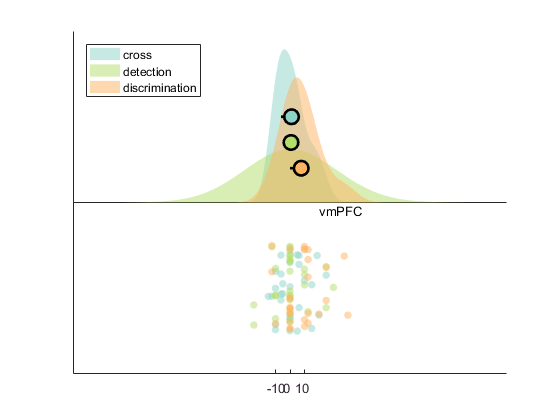

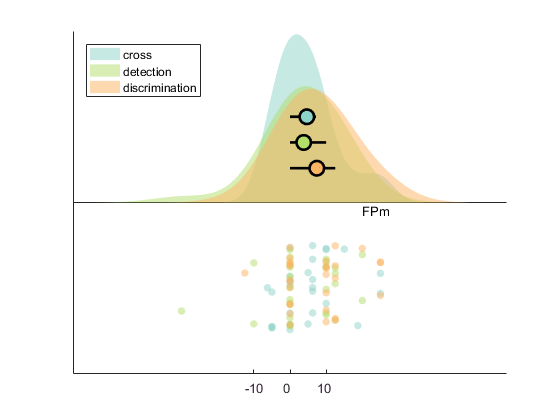

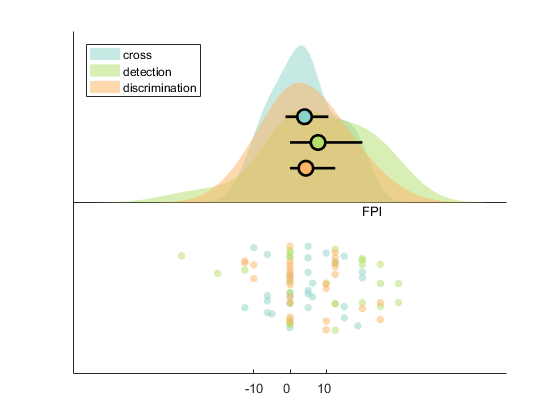

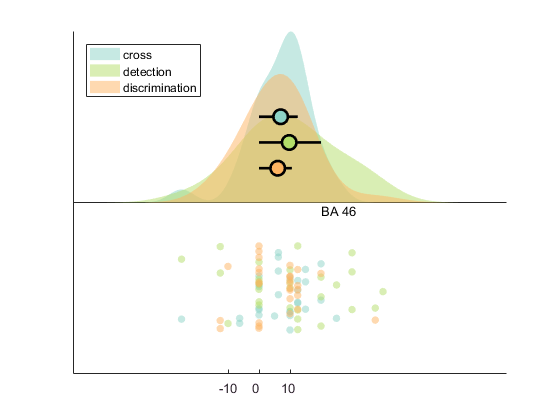

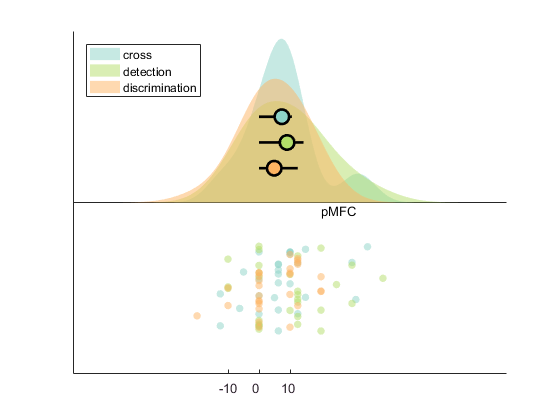

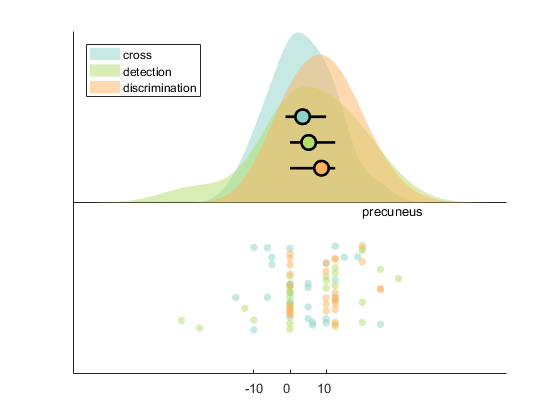

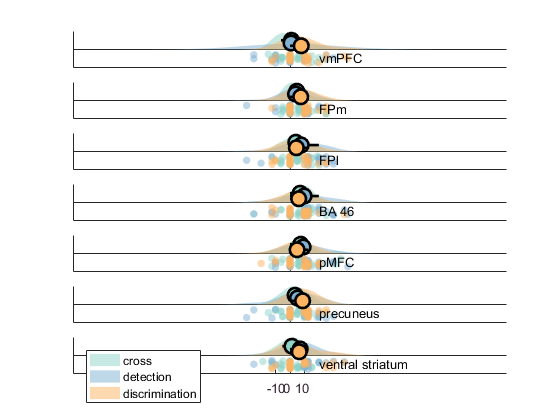

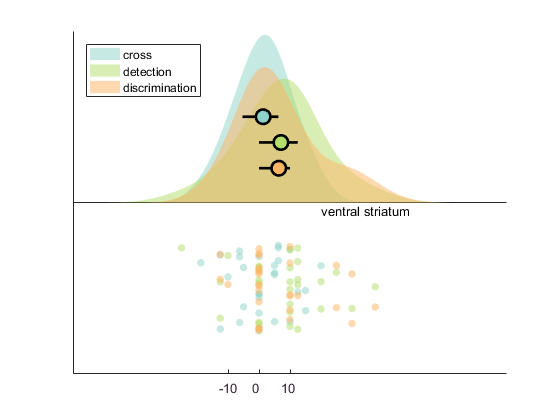

figure; hold on;

b_dis=bar(1:8,nanmean(confidence.group_accuracy,2),'FaceColor',[0.5,0.5,0.5]);
b_dis.FaceColor = 'flat';
% b_dis.CData(1:3,:) = 0.7*ones(3);
errorbar(1:8, nanmean(confidence.group_accuracy,2),nanstd(confidence.group_accuracy')/sqrt(29),'.k')
xticks(1:8);
xticklabels({'FPl','FPm','BA46','v. striatum',...
    'vmPFC','precuneus','pMFC','ventricles'});
xtickangle(45)
title('global confidence')
ylabel('accuracy minus chance')
% fig = gcf;
% s=hgexport('readstyle','presentation');
% s.Format = 'png'; 
% s.Width = 20;
% s.Height = 10;
% hgexport(fig,'figures/confidence_classification',s);

figure; hold on;

b_dis=bar(1:5:36,nanmean(discrimination_confidence,2),'FaceColor',cb(9,:),'BarWidth',0.17);
b_dis.FaceColor = 'flat';
errorbar(1:5:36, nanmean(discrimination_confidence,2),nanstd(discrimination_confidence')/sqrt(29),'.k')

b_det=bar(2:5:37,nanmean(detection_confidence,2),'FaceColor',cb(10,:),'BarWidth',0.17);
b_det.FaceColor = 'flat';
errorbar(2:5:37, nanmean(detection_confidence,2),nanstd(detection_confidence')/sqrt(29),'.k')

b_det2dis=bar(3:5:38,nanmean(detection_to_discrimination,2),'FaceColor',cb(9,:)*0.7,'BarWidth',0.17, 'EdgeColor','none');
b_det2dis.FaceColor = 'flat';
errorbar(3:5:38, nanmean(detection_to_discrimination,2),nanstd(detection_to_discrimination')/sqrt(29),'.k')

b_dis2det=bar(4:5:39,nanmean(discrimination_to_detection,2),'FaceColor',cb(10,:)*0.7,'BarWidth',0.17,'EdgeColor','none');
b_dis2det.FaceColor = 'flat';
errorbar(4:5:39, nanmean(discrimination_to_detection,2),nanstd(discrimination_to_detection')/sqrt(29),'.k')

xticks(1.5+(1:5:36));
xticklabels({'FPl','FPm','BA46','v. striatum',...
    'vmPFC','precuneus','pMFC','ventricles'});
xtickangle(45)
ylabel('accuracy minus chance')
% legend([b_dis,b_det,b_det2dis,b_dis2det],'discrimination','detection','discrimination: c.c', 'detection: c.c','Location','bestoutside')
% fig = gcf;
% s=hgexport('readstyle','presentation');
% s.Format = 'png'; 
% s.Width = 25;
% s.Height = 12;
% hgexport(fig,'figures/confidence_by_task',s);

figure; hold on;

b_YN = bar(-1:10:69,nanmean(YN,2),'BarWidth',0.2, 'FaceColor',cb(2,:));
errorbar(-1:10:69,nanmean(YN,2),nanstd(YN')/sqrt(29),'.k')
b_dis_cross_det = bar(1:10:71,nanmean(dis_cross_det,2),'BarWidth',0.2, 'FaceColor',cb(10,:));
b_dis_cross_det.FaceColor = 'flat';

errorbar(1:10:71,nanmean(dis_cross_det'), nanstd(dis_cross_det')/sqrt(29), '.k');

b_dis_cross_YN = bar(3:10:73,nanmean(dis_cross_YN,2),'BarWidth',0.2, 'FaceColor',cb(9,:));
b_dis_cross_YN.FaceColor = 'flat';

errorbar(3:10:73,nanmean(dis_cross_YN'), nanstd(dis_cross_YN')/sqrt(29), '.k');

xticks(1:10:71);
xticklabels({'FPl','FPm','BA46','v. striatum',...
    'vmPFC','precuneus','pMFC','ventricles'});
xtickangle(45);
ylabel('accuracy minus chance')
% 
% fig = gcf;
% s=hgexport('readstyle','presentation');
% s.Format = 'png'; 
% s.Width = 25;
% s.Height = 12;
% hgexport(fig,'figures/confidence_cross_resp',s);